clear; clc; close all
if bdIsLoaded('flightsim_aircraft')
    set_param('flightsim_aircraft', 'SimulationCommand', 'stop');
end

ac = Aircraft();

empty_mass = 9300;
Ixx = 55800;
Iyy = 63100;
Izz = 118000;

ac.mass.set_mass_properties(empty_mass, Ixx, Iyy, Izz, 0, 0, 0, [0 0 0]);
ac.mass.add_fuel_tank([0, 0, 0], 3000, 'distributed');
ac.mass.add_fuel_tank([-2, 0, 0], 1500, 'distributed');
ac.mass.set_fuel_mass(2400);

ac.geometry.wing_area = 27.87;
ac.geometry.wing_span = 9.14;
ac.geometry.mean_aerodynamic_chord = 3.45;

ac.aero.set_lookup(@F16Lookup);

cfg = ac.get_configurator();

cfg.add_control_surface('name','aileron','surface_type','aileron','classification','primary','axis',[1 0 0], ...
    'max_deflection',deg2rad(20),'min_deflection',deg2rad(-20),'dCl',0.05,'dCm',0,'dCn',0);

cfg.add_control_surface('name','elevator','surface_type','elevator','classification','primary','axis',[0 1 0], ...
    'max_deflection',deg2rad(25),'min_deflection',deg2rad(-25),'dCl',0,'dCm',-0.10,'dCn',0);

cfg.add_control_surface('name','rudder','surface_type','rudder','classification','primary','axis',[0 0 1], ...
    'max_deflection',deg2rad(30),'min_deflection',deg2rad(-30),'dCl',0,'dCm',0,'dCn',-0.08);

cfg.add_propulsive_element('name','F100_PW_229','element_type','turbofan_afterburning','max_output',128992, ...
    'position',[-1.5 0 0],'direction',[1 0 0],'fuel_rate',2.5, ...
    'thrust_model',@(thr,M,alt,V,rho) F100ThrustModel(thr, M, alt, V, rho, 128992));

n_cs = numel(ac.control_surfaces);
n_pe = numel(ac.propulsive_elements);
n_total = n_cs + n_pe;

solver = ac.get_trim_solver();
solver.use_fmincon = true;
solver.trim_tolerance = 1e-5;
solver.max_iterations = 500;

%% TRIM 1
trimcase = struct();
alt_cruise = 9144;
mach_cruise = 0.6;
[~, a_cruise, ~, ~] = atmosisa(alt_cruise);
V_cruise = mach_cruise * a_cruise;
fprintf('Altitude: %.0f m, Mach: %.3f\n', alt_cruise, mach_cruise);

Altitude: 9144 m, Mach: 0.600


[x_cruise, u_cruise, ok_cruise] = solver.solve_trim(alt_cruise, V_cruise, 0, 0, 0);
if ok_cruise
    alpha_cruise = atan2(x_cruise(6), x_cruise(4));
    fprintf('Alpha: %.3f deg\n', rad2deg(alpha_cruise));
    fprintf('Theta: %.3f deg\n', rad2deg(x_cruise(8)));
    fprintf('Elevator: %.3f deg\n', rad2deg(u_cruise(2)));
    fprintf('Throttle: %.1f%%\n', u_cruise(4)*100);
end

Alpha: 6.953 deg


Theta: 6.953 deg


Elevator: -3.088 deg


Throttle: 31.7%


trimcase.cruise = struct('alt_m',alt_cruise,'V_mps',V_cruise,'Mach',mach_cruise,'x',x_cruise,'u',u_cruise,'ok',ok_cruise);

%% TRIM 2
alt_climb = 5000;
mach_climb = 0.5;
gamma_climb = deg2rad(5);
[~, a_climb, ~, ~] = atmosisa(alt_climb);
V_climb = mach_climb * a_climb;
fprintf('Altitude: %.0f m, Mach: %.3f, Gamma: %.1f deg\n', alt_climb, mach_climb, rad2deg(gamma_climb));

Altitude: 5000 m, Mach: 0.500, Gamma: 5.0 deg


[x_climb, u_climb, ok_climb] = solver.solve_trim(alt_climb, V_climb, gamma_climb, 0, 0);
if ok_climb
    alpha_climb = atan2(x_climb(6), x_climb(4));
    fprintf('Alpha: %.3f deg\n', rad2deg(alpha_climb));
    fprintf('Theta: %.3f deg\n', rad2deg(x_climb(8)));
    fprintf('Elevator: %.3f deg\n', rad2deg(u_climb(2)));
    fprintf('Throttle: %.1f%%\n', u_climb(4)*100);
end

Alpha: 5.188 deg


Theta: 10.188 deg


Elevator: -5.415 deg


Throttle: 37.2%


trimcase.climb = struct('alt_m',alt_climb,'V_mps',V_climb,'gamma_rad',gamma_climb,'x',x_climb,'u',u_climb,'ok',ok_climb);

%% TRIM 3
alt_dash = 5000;
mach_dash = 1.2;
[~, a_dash, ~, ~] = atmosisa(alt_dash);
V_dash = mach_dash * a_dash;
fprintf('Altitude: %.0f m, Mach: %.3f\n', alt_dash, mach_dash);

Altitude: 5000 m, Mach: 1.200


[x_dash, u_dash, ok_dash] = solver.solve_trim(alt_dash, V_dash, 0, 0, 0);
if ok_dash
    alpha_dash = atan2(x_dash(6), x_dash(4));
    fprintf('Alpha: %.3f deg\n', rad2deg(alpha_dash));
    fprintf('Theta: %.3f deg\n', rad2deg(x_dash(8)));
    fprintf('Elevator: %.3f deg\n', rad2deg(u_dash(2)));
    fprintf('Throttle: %.1f%%\n', u_dash(4)*100);
end

Alpha: -0.356 deg


Theta: -0.356 deg


Elevator: -2.794 deg


Throttle: 80.9%


trimcase.dash = struct('alt_m',alt_dash,'V_mps',V_dash,'Mach',mach_dash,'x',x_dash,'u',u_dash,'ok',ok_dash);

%% STABILITY

A = [];
B = [];
modes = struct();

if ok_cruise
    ac.state.set_full_state(x_cruise);
    ac.set_controls_from_vector(u_cruise);
    stab = StabilityAnalysis(ac);
    stab.set_trim(x_cruise, u_cruise);
    [A, B] = stab.linearize(1e-6, 1e-6);
    stab.analyze_modes();
    modes = stab.get_modes_summary();
    
    fprintf('State matrix A: %dx%d\n', size(A,1), size(A,2));
    fprintf('Input matrix B: %dx%d\n', size(B,1), size(B,2));
    
    fprintf('\nDynamic Modes:\n');
    
    if isfield(modes, 'phugoid') && ~isempty(modes.phugoid)
        fprintf('  phugoid:\n');
        fprintf('    Damping: %.4f\n', modes.phugoid.damping);
        fprintf('    Period: %.2f s\n', modes.phugoid.period);
    end
    
    if isfield(modes, 'short_period') && ~isempty(modes.short_period)
        fprintf('  short_period:\n');
        fprintf('    Damping: %.4f\n', modes.short_period.damping);
        fprintf('    Period: %.2f s\n', modes.short_period.period);
    end
    
    if isfield(modes, 'dutch_roll') && ~isempty(modes.dutch_roll)
        fprintf('  dutch_roll:\n');
        fprintf('    Damping: %.4f\n', modes.dutch_roll.damping);
        fprintf('    Period: %.2f s\n', modes.dutch_roll.period);
    end
    
    if isfield(modes, 'roll_subsidence') && ~isempty(modes.roll_subsidence)
        fprintf('  roll_subsidence:\n');
        fprintf('    Time constant: %.3f s\n', modes.roll_subsidence.time_constant);
    end
    
    if isfield(modes, 'spiral') && ~isempty(modes.spiral)
        fprintf('  spiral:\n');
        fprintf('    Time constant: %.3f s\n', modes.spiral.time_constant);
        fprintf('    Stable: %s\n', mat2str(modes.spiral.stable));
    end
end

State matrix A: 12x12


Input matrix B: 12x4



Dynamic Modes:


  phugoid:


    Damping: 0.0338


    Period: 37.87 s


  dutch_roll:


    Damping: 0.0599


    Period: 2.90 s


  spiral:


    Time constant: 111.269 s


    Stable: true



%% TAKEOFF & LANDING
to = TakeoffAnalysis(ac);
[TO_m, TO_res] = to.calculate_takeoff(0, 0, inf);
fprintf('Takeoff distance: %.0f m\n', TO_m);

Takeoff distance: 436 m



ld = LandingAnalysis(ac);
[LD_m, LD_res] = ld.calculate_landing(0, 0, inf);
fprintf('Landing distance: %.0f m\n', LD_m);

Landing distance: 937 m



%% PERFORMANCE
alt_grid = (0:2000:18000).';
V_grid = (100:20:600).';

perf = PerformanceAnalysis(ac);
opts = struct();
opts.alpha_only = true;
opts.use_lift_balance = true;
opts.throttle_full = 1.0;

fprintf('Running performance package...\n');

Running performance package...


pkg = perf.run_package(alt_grid, V_grid, opts);
fprintf('Complete.\n');

Complete.


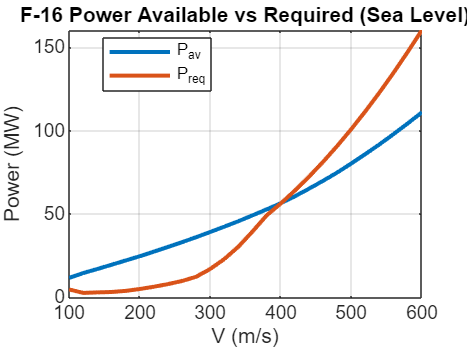


V = pkg.grid.V;
Pav_SL = pkg.grid.Pav_W(1,:);
Preq_SL = pkg.grid.Preq_W(1,:);
Tav_SL = pkg.grid.thrust_N(1,:);
Treq_SL = pkg.grid.drag_N(1,:);
ROC_SL = pkg.grid.ROC_mps(1,:);

%% PLOTS - POWER
figure
plot(V, Pav_SL/1e6, 'LineWidth', 2); hold on
plot(V, Preq_SL/1e6, 'LineWidth', 2);
grid on
xlabel('V (m/s)')
ylabel('Power (MW)')
legend('P_{av}','P_{req}','Location','best')
title('F-16 Power Available vs Required (Sea Level)')

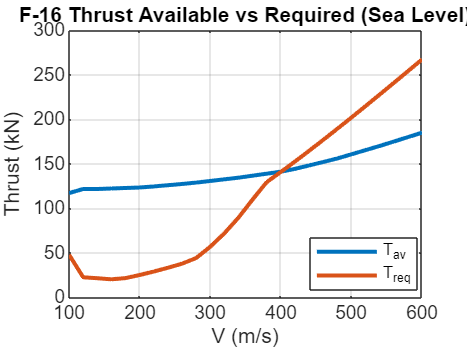


%% PLOTS - THRUST
figure
plot(V, Tav_SL/1e3, 'LineWidth', 2); hold on
plot(V, Treq_SL/1e3, 'LineWidth', 2);
grid on
xlabel('V (m/s)')
ylabel('Thrust (kN)')
legend('T_{av}','T_{req}','Location','best')
title('F-16 Thrust Available vs Required (Sea Level)')

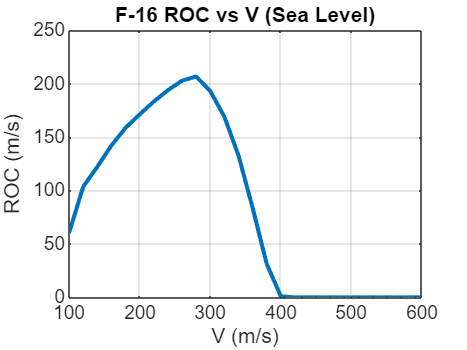


%% PLOTS - ROC
figure
plot(V, ROC_SL, 'LineWidth', 2);
grid on
xlabel('V (m/s)')
ylabel('ROC (m/s)')
title('F-16 ROC vs V (Sea Level)')

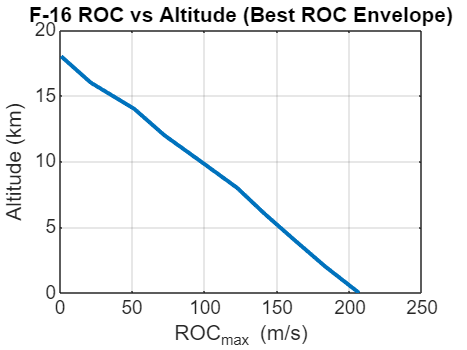


%% PLOTS - ENVELOPE
figure
plot(pkg.climb_schedule.ROC_opt, pkg.climb_schedule.altitude/1000, 'LineWidth', 2);
grid on
xlabel('ROC_{max} (m/s)')
ylabel('Altitude (km)')
title('F-16 ROC vs Altitude (Best ROC Envelope)')


%% SAVE
out = struct();
out.trim = trimcase;
out.stability = struct('A',A,'B',B,'modes',modes);
out.takeoff = struct('distance_m',TO_m,'results',TO_res);
out.landing = struct('distance_m',LD_m,'results',LD_res);
out.performance = pkg;
